clear variables;

% [data,queries,gt,dataname] = get_data("DinoV2",100);
% [data,queries,gt,dataname] = get_data("GloVe",-1);
% [data,queries,gt,dataname] = get_data("GloVe200",-1);
% [data,queries,gt,dataname] = get_data("PubMed",-1);
% [data,queries,gt,dataname] = get_data("Laion",-1);
% [data,queries,gt,dataname] = get_data("Wiki",100);
% [data,queries,gt,dataname] = get_data("Uniform",250);
% [data,queries,gt,dataname] = get_data("Uniform",500);
% [data,queries,gt,dataname] = get_data("Uniform",750);
[data,queries,~,dataname] = get_data("Uniform",64);

data = data(1:100000,:);

try
    load(strcat("/Users/newrichard/git/matlab/MetricSearch/2026_rabbits/_rabbit_new_",dataname,".mat"));
catch
    disp(strcat("no data file for ",dataname));
end

rrots = getRandomRotations(size(data,2),1,0);
rrot = squeeze(rrots(1,:,:));
data = data * rrot;

queries = queries * rrot;
qDists = data * queries';
[~,gt] = maxk(qDists,201);

intraDataDists = data * data(1:1000,:)';
[~,gt_self_join] = maxk(intraDataDists,201);



tic;
tq_quants_col_major = tq_quant_dequant(data');
tq_quants = tq_quants_col_major';
toc;

Elapsed time is 0.273618 seconds.



% could maybe benefit from normalisation?
% tq_quants = tq_quants ./ euc(zeros(1,size(tq_quants,2)),tq_quants);


noOfData = size(data,1);

if ~exist("rb_quants","var")
    rq_data = zeros(noOfData,size(data,2),"int8");
    rb_goodness = zeros(noOfData,1);
    tic;
    for i = 1 : noOfData
        if mod(i,5000) == 0
            disp(i);
        end
        [rabitQ,g] = rabit2_mod(data(i,:));
        rq_data(i,:) = rabitQ;
        rb_goodness(i) = g;
    end
    toc;
    %adjust and normalise for comparison using scalar product
    rb_centred = single(rq_data) - 1.5;
    rb_quants = rb_centred ./ euc(zeros(1,size(rb_centred,2)),rb_centred);

    save(strcat("/Users/newrichard/git/matlab/MetricSearch/2026_rabbits/_rabbit_new_",dataname),"rb_quants")
else
    rb_goodness = zeros(noOfData,1);
    for i = 1 : size(data,1)
        rb_goodness(i) = data(i,:) * rb_quants(i,:)';
    end
end


rb_goodness = zeros(noOfData,1);
for i = 1 : size(data,1)
    rb_goodness(i) = data(i,:) * rb_quants(i,:)';
end




% rb_quants = rb_quants_unnormed ./ euc(zeros(1,size(rb_quants,2)),rb_quants_unnormed);
% rb_goodness = zeros(size(rb_quants,1),1);
% for i = 1 : size(rb_quants,1)
%     rb_goodness(i) = data(i,:) * rb_quants(i,:)';
% end


tic;
[evp_quants,evp_goodness] = getEVP_1_2(data);
toc;

Elapsed time is 0.268070 seconds.




evp_res = evp_quants * evp_quants(1:1000,:)' ./ evp_goodness ./ evp_goodness(1:1000)';
[~,evp_ord] = maxk(evp_res,101);
length(intersect(evp_ord(:,1),gt_self_join(:,1)));

evp_res_raw = evp_quants * evp_quants(1:1000,:)';
[~,evp_raw_ord] = maxk(evp_res_raw,101);
length(intersect(evp_raw_ord(:,1),gt_self_join(:,1)));

tq_res = tq_quants * tq_quants(1:1000,:)';
[~,tq_ord] = maxk(tq_res,101);
length(intersect(tq_ord(:,1),gt_self_join(:,1)));

rb_res = rb_quants * rb_quants(1:1000,:)' ./ rb_goodness ./ rb_goodness(1:1000)';
[~,rb_ord] = maxk(rb_res,101);
length(intersect(tq_ord(:,1),gt_self_join(:,1)));

at1s = [30,100];
for at1 = 1:length(at1s)
intersectionsXat100 = zeros(4,size(queries,1));
for i = 1 : size(queries,1)
    intersectionsXat100(1,i) = length(intersect(evp_ord(2:end,i),gt_self_join(2:at1s(at1)+1,i)));
    intersectionsXat100(2,i) = length(intersect(tq_ord(2:end,i),gt_self_join(2:at1s(at1)+1,i)));
    intersectionsXat100(3,i) = length(intersect(rb_ord(2:end,i),gt_self_join(2:at1s(at1)+1,i)));
    intersectionsXat100(4,i) = length(intersect(evp_raw_ord(2:end,i),gt_self_join(2:at1s(at1)+1,i)));
end
disp(dataname);
disp("evp, tq, rb, evp unadjusted");
disp(at1s(at1));
mean(intersectionsXat100,2)
end

Uniform64


evp, tq, rb, evp unadjusted


    30



ans =    11.5460
   17.4620
   15.9340
   11.6650


Uniform64


evp, tq, rb, evp unadjusted


   100



ans =    25.1500
   38.1330
   34.4690
   25.4450


at1 = 30;
kRange = 1:100

kRange =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


meanResses = zeros(4,100);

for at2 = kRange
    resses = zeros(3,1000);
    for i = 1 : size(queries,1)
        resses(1,i) = length(intersect(evp_ord(2:at2+1,i),gt_self_join(2:at1 + 1,i)));
        resses(2,i) = length(intersect(tq_ord(2:at2+1,i),gt_self_join(2:at1 + 1,i)));
        resses(3,i) = length(intersect(rb_ord(2:at2+1,i),gt_self_join(2:at1 + 1,i)));
        resses(4,i) = length(intersect(evp_raw_ord(2:at2+1,i),gt_self_join(2:at1 + 1,i)));
    end
    meanResses(:,at2) = mean(resses,2);
end

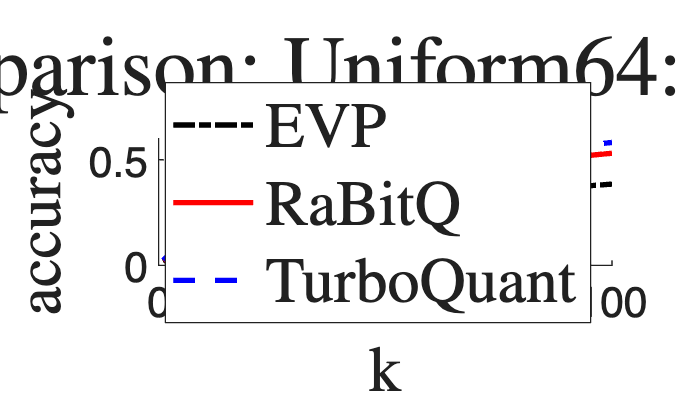


figure;
ax=gca;
ax.FontSize=16;
title(strcat("$\widehat{s_i},\widehat{s_j}$ comparison: ", dataname,": ",num2str(at1),"@k recall"),"Interpreter","latex",FontSize=32);
ylabel("accuracy","Interpreter","latex",FontSize=24);
xlabel("k","Interpreter","latex",FontSize=24);
hold on
plot(kRange,meanResses(1,kRange)/at1,LineWidth=2,Color="black",LineStyle="-.");
plot(kRange,meanResses(3,kRange)/at1,LineWidth=2,Color="red",LineStyle="-");
plot(kRange,meanResses(2,kRange)/at1,LineWidth=2,Color="blue",LineStyle="--");
% plot(kRange,meanResses(4,kRange)/at1,LineWidth=2,Color="magenta",LineStyle=":");
legend("EVP","RaBitQ","TurboQuant","Interpreter","latex",location="best",FontSize=24);
hold off;